clear

Read in AC Load (from Menzies Building)

data = readtable("data.xlsx");
%Remove the redundant data
data = removevars(data, ["meter_serial", "meter_desc", "expwh","difference_exp_kwh","interval_start", "waste", "meter_id", "tariff_id", "impwh","stot", "pftot","md","qtot","difference_imp_kwh","epoch_timestamp","season_class_id","season_profile_id","day","week_number"]);

Read in DC load (From Mendeley Data)

DCData = readtable("OnlineData\Commercial-Office.csv");


% Need to wrap days so that it starts on the same day of the week as the AC
% load.
numElementsToWrap = 8760-(24*6);
numTotalElements = size(DCData(:,1));
% Shift the middle portion to the beginning and wrap it
startIndex = numTotalElements - numElementsToWrap + 1;
DCDataWrapped = vertcat(DCData(startIndex:end,"Power_kW_"), DCData(1:startIndex - 1,"Power_kW_"));

Concatanate the data so there is one data set. 

data = horzcat(data,DCDataWrapped);
data = renamevars(data, "Power_kW_","DC"); %Rename the DC electrical load to DC
data = renamevars(data, "ptot","AC");      %Rename the AC electrical load to AC

Clean up the Data

%Fill data with no information. The previous value is used.
[data,missingIndices] = fillmissing(data,"previous");
%fill the anomalies caused by loadshedding. Lower 4.75 percentile of data
%is replaced by linear interpolation.
[data,outlierIndices5,thresholdLow5,thresholdHigh5] = filloutliers(data,...
    "linear","percentiles",[4.75 100],"DataVariables","AC");

**Add some rows with indicator variables to help point towards patterns.**

**Will need to play with this to see what gives the best results!**

%Add a column with the day of the week (mon-1 & sun-7)
data.day = day(data.date, "iso-dayofweek");

%Conditions for day hours. 
low_time = 0.29; %7am
up_time = 0.75;  %6pm
%Logical arrays for adding conditions.
weekDayCondition = (data.day ~= 6) & (data.day ~= 7) ;
SatCondition     = (data.day == 6);
SunCondition     = (data.day == 7);
wrkHrsCondition  = (data.time >= low_time) & (data.time <= up_time) & (data.day ~= 6) & (data.day ~= 7);
dayTimeCondition = (data.time >= low_time) & (data.time <= up_time);

%Adding indicators to the table
data.weekDay    = double(weekDayCondition);
data.Sat         = double(SatCondition);
data.Sun        = double(SunCondition);
data.wrkHr      = double(wrkHrsCondition);
data.dayTime    = double(dayTimeCondition);

%converting tou to a hot one indexed variable
data.tou = categorical(data.tou);
data = [data onehotencode(data(:,"tou")) ];

%Removing date (have tstamp),
% Removing time(have working hours and daytime)
%Removing day (have Weekday, Sat, Sun)
%Removing tou (have tou_id & hot one indexed tou)
%Removing [NULL] column that  comes from the hot one indexing of tou
data = removevars(data,["date","time","day","tou", "[NULL]"]);


data

data = 8760×12 table
           tstamp             AC      tou_id     DC      weekDay    Sat    Sun    wrkHr    dayTime    Off-Peak    Peak    Standard
    ____________________    ______    ______    _____    _______    ___    ___    _____    _______    ________    ____    ________

    01-Jan-2022 00:00:00    96.855      3         230       0        1      0       0         0          1         0         0    
    01-Jan-2022 01:00:00    97.053      3       229.2       0        1      0       0         0          1         0         0    
    01-Jan-2022 02:00:00    97.229      3     

summary(data)

Variables:

    tstamp: 8760×1 datetime

        Values:

            Min       01-Jan-2022 00:00:00
            Median    02-Jul-2022 11:30:00
            Max       31-Dec-2022 23:00:00

    AC: 8760×1 double

        Values:

            Min         79.12 
            Median     165.23 
            Max        304.46 

    tou_id: 8760×1 double

        Values:

            Min          2    
            Median       3    
            Max          4    

    DC: 8760×1 double

        Properties:
            Description:  Power [kW]
        Values:

            Min        130.7  
            Median     247.3  
            Max        874.9  

    weekDay: 8760×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    Sat: 8760×1 double

        Values:

            Min          0    
            Median       0    
     

 Making an AC and a DC data set

dataAC = removevars(data,"DC");
dataDC = removevars(data,"AC");

**Train model**

%Need to get rid of date time. Think Imma keep Hour

labels = data.Properties.VariableNames;
data.day = day(data.tstamp, "dayofyear");
data.time = hour(data.tstamp);
data =  removevars(data,"tstamp");
%data=normalize(data(:,["AC","DC", "day", "time"] ));

% minAC = min(data.AC(:))
% minDC = min(data.DC(:))
% minDay = min(data.day(:));
% minTime = min(data.time(:));
% 
% maxAC = max(data.AC(:))
% maxDC = max(data.DC(:))
% maxDay = max(data.day(:));
% maxTime = max(data.time(:));
% 
% data.AC = (data.AC(:) - minAC)/(maxAC-minAC);
% data.DC = (data.DC(:) -minDC)/(maxDC - minDC);
% data.day = (data.day(:) - minDay)/(maxDay - minDay);
% data.time = (data.time(:) -minTime)/(maxTime - minTime);

summary(data)

Variables:

    AC: 8760×1 double

        Values:

            Min         79.12 
            Median     165.23 
            Max        304.46 

    tou_id: 8760×1 double

        Values:

            Min          2    
            Median       3    
            Max          4    

    DC: 8760×1 double

        Properties:
            Description:  Power [kW]
        Values:

            Min        130.7  
            Median     247.3  
            Max        874.9  

    weekDay: 8760×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    Sat: 8760×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Sun: 8760×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    wr

For lstm I want to break the time series up into shorter batches

Batch size 7days. 

Create cell array with a cell for each batch

Each batch is 7days of observations (rows are variables and columns are time steps)

numDays = 7;

height = ceil(size(data(:,1))/(numDays*24));
dataCell = cell(height(1), 1);

for i = 1:numel(dataCell)
    %Get the range of rows that you need for this batch
    startIdx = (i-1)*numDays*24 + 1;
    endIdx   = min(i*numDays*24, size(data(:,1)));
    %Store the batch in an array
    currentBatch = table2array(data(startIdx:endIdx, :));
    %transpose array so that columns are timesteps
    currentBatch = transpose(currentBatch);
    %Store in cell array
    dataCell{i} = currentBatch;
end


Split data for Training and testing

numObservations = numel(dataCell);
perctSplit = 0.9

perctSplit = 0.9000


idxTrain = 1:floor(perctSplit*numObservations);
idxTest = floor(perctSplit*numObservations)+1:numObservations;
dataTrain = dataCell(idxTrain);
dataTest = dataCell(idxTest);

To forecast the values of future time steps of a sequence, specify the targets as the training sequences with values shifted by one time step. In other words, at each time step of the input sequence, the LSTM neural network learns to predict the value of the next time step. The predictors are the training sequences without the final time step.

**NOTE Try to change TTrain to only hold the future values of AC and DC since those are the values I am interested in?**

for n = 1:numel(dataTrain)
    %select batches one at a time.
    X = dataTrain{n}; 
    %Set the full sequence minus the last value as the predictors 
    XTrain{n} = X(:,1:end-1);
    %Set the Sequence but one step forward as the targets
    TTrain{n} = X(:,2:end);
end 

%Do the same for the test data
for n  = 1:numel(dataTest);
    X = dataTest{n};
    XTest{n} = X(:,1:end-1);
    TTest{n} = X(:,2:end);
end

We need to normailse the data to have a zero mean and unit variance. 

Note, Use the same mean and std deviation that you calculated on the training data on the test data. 

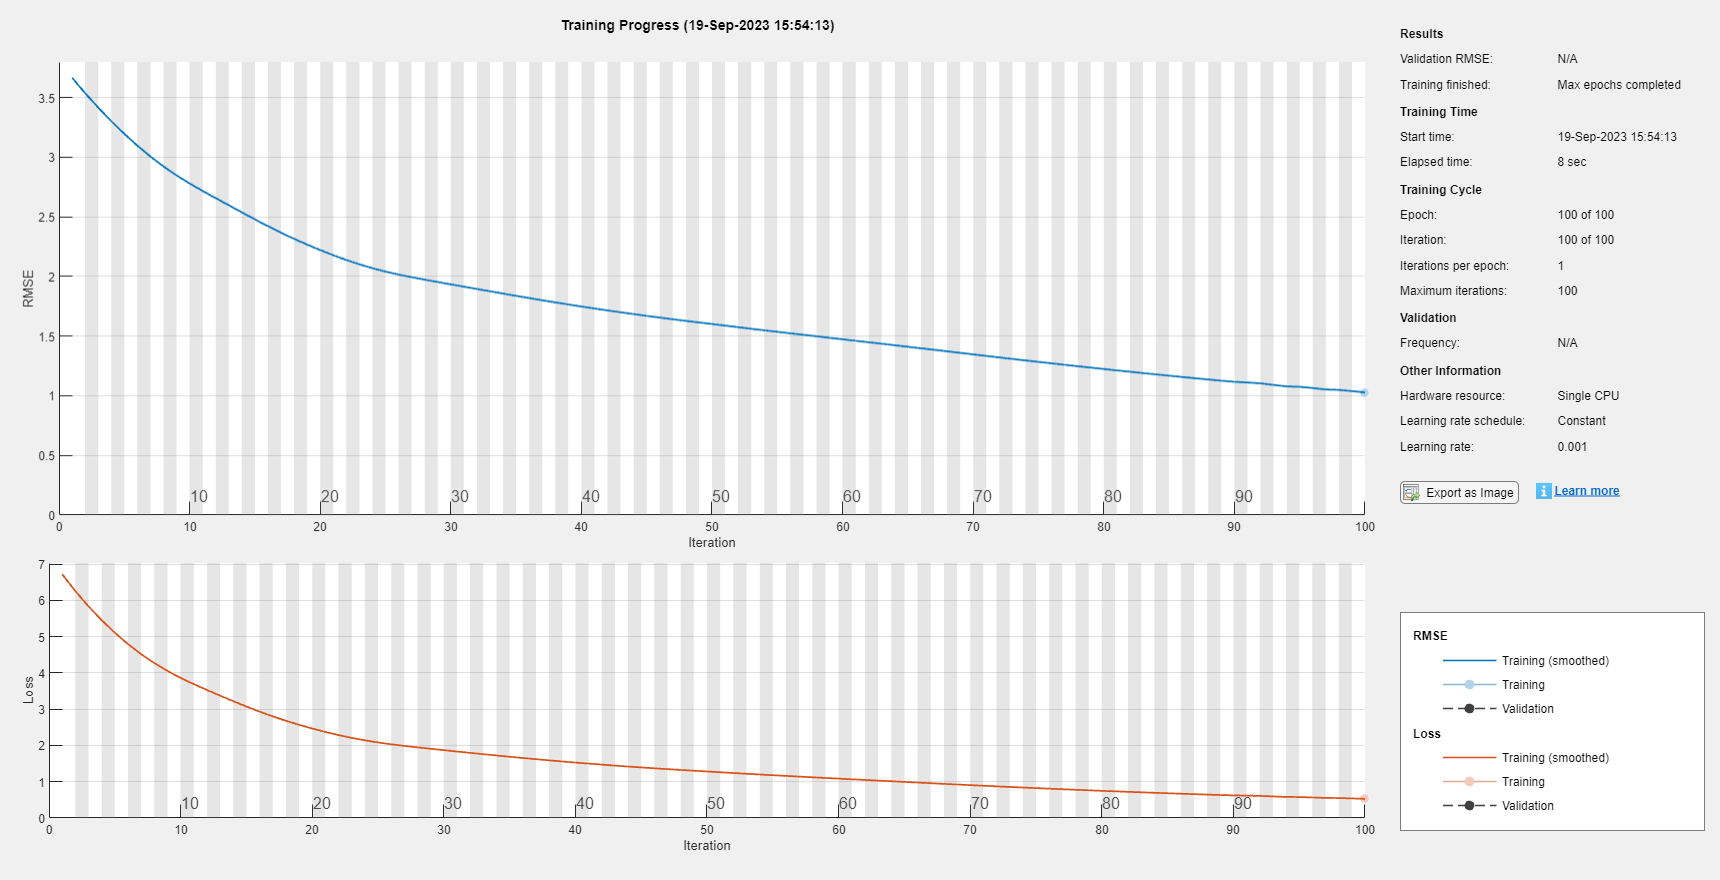

%Mean of training 
meanX = mean(cat(2,XTrain{:}),2);
sigmaX = std(cat(2,XTrain{:}),0,2);
%Mean of training Targets
meanT = mean(cat(2,TTrain{:}),2);
sigmaT = std(cat(2,TTrain{:}),0,2);

%apply to the training data
for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n}-meanX)./sigmaX;
    TTrain{n} = (TTrain{n}-meanT)./sigmaT;
end
%apply to the test data
for n = 1:numel(XTest)
    XTest{n} = (XTest{n}-meanX)./sigmaX;
 %   TTest{n} = (TTest{n}-meanT)./sigmaT;
end

numChannels = size(dataCell{1},1); 

layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)
    regressionLayer];


options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(XTrain,TTrain,layers,options);

**Test Network **

using the Test data and the trained net to make predictions.

preds = predict(net, XTest, SequencePaddingDirection="left");

Undo the standardisation on the predictions

for n = 1:numel(preds)
    preds{n} = (preds{n}.*sigmaT)+meanT;
end

To test the RMSE

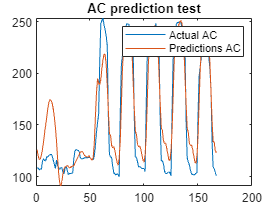

for i = 1:size(preds,1)
    for k = 1:size(preds{1}(:,1))
        rmse(i,k) = sqrt(mean((preds{i}(k,:) - TTest{i}(k,:)).^2,"all"));
        mape(i,k) =   mean(abs((TTest{i}(k,:)-preds{i}(k,:))./TTest{i}(k,:)),"all")*100;
    end
end



figure
plot(TTest{1}(1,:));
hold on
plot(preds{1}(1,:));
hold off
legend("Actual AC", "Predictions AC");
title("AC prediction test")

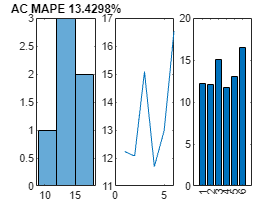


figure
subplot(1,3,1)
histogram(mape(:,1))
title("AC MAPE " + mean(mape(:,1)) +"%" )
subplot(1,3,2)
plot(mape(:,1))
subplot(1,3,3)
bar(mape(:,1))

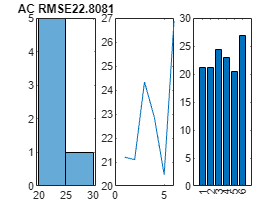

figure

subplot(1,3,1)
histogram(rmse(:,1))
title("AC RMSE" + mean(rmse(:,1)))
subplot(1,3,2)
plot(rmse(:,1))
subplot(1,3,3)
bar(rmse(:,1))

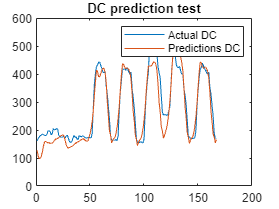


figure
plot(TTest{1}(3,:));
hold on
plot(preds{1}(3,:));
hold off
legend("Actual DC", "Predictions DC");
title("DC prediction test")

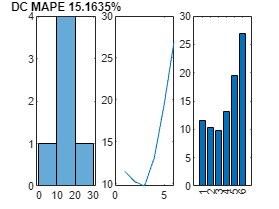


figure
subplot(1,3,1)
histogram(mape(:,3))
title("DC MAPE " + mean(mape(:,3)) +"%" )
subplot(1,3,2)
plot(mape(:,3))
subplot(1,3,3)
bar(mape(:,3))

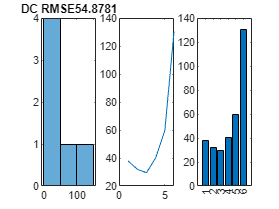


figure
subplot(1,3,1)
histogram(rmse(:,3))
title("DC RMSE" + mean(rmse(:,3)))
subplot(1,3,2)
plot(rmse(:,3))
subplot(1,3,3)
bar(rmse(:,3))

**Closed loop forcasting to predict full day ahead :)**

Predict values **t ** through to **t+k ** when you have data collected for steps **1 ** through to **t-1;**

idx = 1;
X = XTest{idx};
T = TTest{idx};

net = resetState(net);
offset = 5*24;
[net,Z] = predictAndUpdateState(net,X);

numPredictionTimeSteps = 24;
Xt = Z(:,end);
Y = zeros( numChannels, numPredictionTimeSteps); % the 2 is for the 2 output channels

for t = 1:numPredictionTimeSteps
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);
    Xt = Y(:,t);
end


Visualise closed loop prediction

numTimeSteps = offset+numPredictionTimeSteps;

for n = 1:numel(Y)
    Y{n} = (Y{n}.*sigmaT)+meanT;
end

Brace indexing is not supported for variables of this type.


figure
t=tiledlayout(2,1);
title(t, "Day ahead forecasting for Electrical load")

nexttile 
plot(T(1,1:offset))
hold on 
plot(offset:numTimeSteps,[T(1,offset) Y(1,:)],'--')
ylabel("AC day ahead forcast")
legend("Input","24h Forecast")

nexttile 
plot(T(3,1:offset))
hold on 
plot(offset:numTimeSteps,[T(3,offset) Y(3,:)],'--')
ylabel("AC day ahead forcast")
legend("Input","24h Forecast")



